clear; close all; clc;

load("data.mat");

% -------------------- Grab arrays (your structure) ------------------------
pressure    = out.pressure.signals.values;
hum         = out.hum.signals.values;        % change field name if needed
temp        = out.temp.signals.values;       % change field name if needed

acutal_rpm  = out.feedback_reference.signals(1).values;
set_rpm     = out.feedback_reference.signals(2).values;

% -------------------- Trim: drop first 1000, keep next 1500 ---------------
N_drop = 1000;
N_keep = 1500;

minLen = min([numel(pressure), numel(hum), numel(temp), numel(acutal_rpm), numel(set_rpm)]);
if minLen < (N_drop + N_keep)
    error("Not enough samples. Need at least %d, but shortest signal has %d.", N_drop+N_keep, minLen);
end

idx = (N_drop+1):(N_drop+N_keep);

pressure   = pressure(idx);
hum        = hum(idx);
temp       = temp(idx);
acutal_rpm = acutal_rpm(idx);
set_rpm    = set_rpm(idx);

% -------------------- Real-world time conversion --------------------------
% You KNOW: 1500 samples span 100 real-world seconds (0..100)
T_total = 100;                            % seconds
time    = linspace(0, T_total, N_keep).'; % seconds
dt      = time(2) - time(1);

% -------------------- Only show first 76400.94 ms -------------------------
T_show_ms = 76400.94;          % ms
T_show_s  = T_show_ms / 1000;  % seconds

N_show = floor(T_show_s/dt) + 1;   % number of samples to include from t=0
N_show = max(2, min(N_show, N_keep));

time      = time(1:N_show);
pressure  = pressure(1:N_show);
hum       = hum(1:N_show);
temp      = temp(1:N_show);
acutal_rpm = acutal_rpm(1:N_show);
set_rpm    = set_rpm(1:N_show);

% --------------------------- Derived speeds -------------------------------
gear_ratio = 8;        % 1/x
r_mm       = 50/2;     % mm
circ_mm    = 2*pi*r_mm;

acutal_speed = (acutal_rpm./gear_ratio) .* (circ_mm/60);  % mm/s
set_speed    = (set_rpm./gear_ratio)    .* (circ_mm/60);  % mm/s

% ---------------------------- Global styling ------------------------------
set(groot, ...
    "defaultTextInterpreter","latex", ...
    "defaultAxesTickLabelInterpreter","latex", ...
    "defaultLegendInterpreter","latex", ...
    "defaultAxesFontSize",12, ...
    "defaultAxesLineWidth",1.1, ...
    "defaultLineLineWidth",2.2);

fprintf("Showing 0 to %.5f s (from %.2f ms). Samples shown: %d / %d\n", ...
    time(end), T_show_ms, N_show, N_keep);

Showing 0 to 76.38426 s (from 76400.94 ms). Samples shown: 1146 / 1500


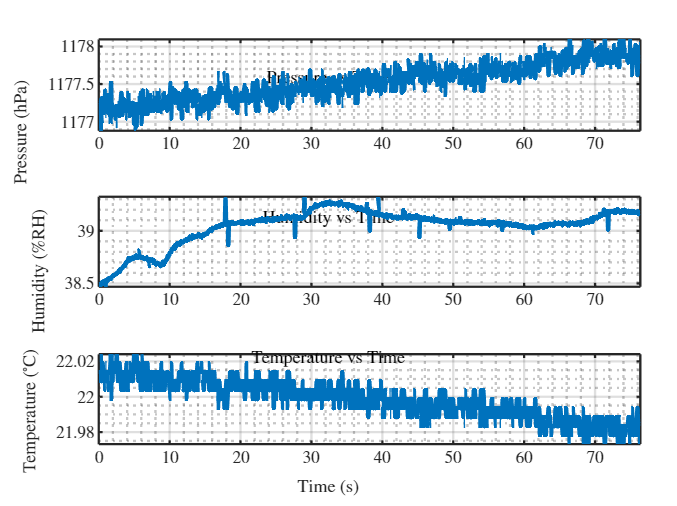


% ===================== Figure 1: Environment signals ======================
f1 = figure("Color","w","Name","Environment");
t1 = tiledlayout(f1,3,1,"TileSpacing","compact","Padding","compact");

ax1 = nexttile;
plot(time, pressure); grid on; grid minor;
ylabel("Pressure (hPa)");
title("Pressure vs Time");

ax2 = nexttile;
plot(time, hum); grid on; grid minor;
ylabel("Humidity (\%RH)");
title("Humidity vs Time");

ax3 = nexttile;
plot(time, temp); grid on; grid minor;
ylabel("Temperature ($^\circ$C)");
xlabel("Time (s)");
title("Temperature vs Time");

linkaxes([ax1 ax2 ax3],"x");
xlim([0 time(end)]);

% ===================== Figure 2: RPM + Speed tracking =====================
f2 = figure("Color","w","Name","Tracking");
t2 = tiledlayout(f2,2,1,"TileSpacing","compact","Padding","compact");

ax4 = nexttile;
plot(time, set_rpm, "--"); hold on;
plot(time, acutal_rpm, "-");
grid on; grid minor;
ylabel("RPM");
title("RPM Tracking");
legend("Set RPM","Actual RPM","Location","best");
xlim([0 time(end)]);

ax5 = nexttile;
plot(time, set_speed, "--"); hold on;
plot(time, acutal_speed, "-");
grid on; grid minor;
ylabel("Speed (mm/s)");
xlabel("Time (s)");
title("Linear Speed Tracking");
legend("Set speed","Actual speed","Location","best");
xlim([0 time(end)]);

linkaxes([ax4 ax5],"x");

% ------------------------------- Export -----------------------------------
exportgraphics(f1,"env_signals.png","Resolution",300);

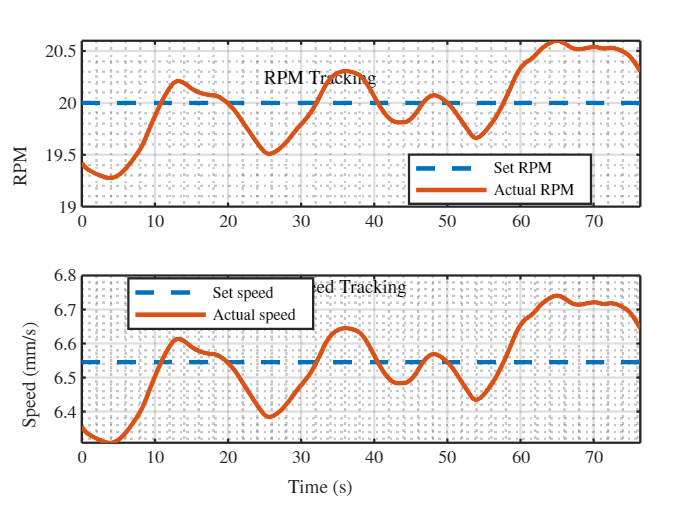

exportgraphics(f2,"tracking_signals.png","Resolution",300);